# Example 9.1: `Computing the Error Ellipse`

Nicholas O'Donoughue 1 July 2019

*Given the **covariance** matrix *$	\mathrm{\bf C} = \left[\begin{array}{cc} \sigma_x^2 & \sigma_{xy} \\ \sigma_{yx} & \sigma_y^2\end{array}\right] = \left[\begin{array}{cc} 10 & 3 \\ 3 & 5\end{array}\right],$ *find the equation for the error ellipse that describes a 90% confidence interval. Assume the estimate is unbiased (***b***=***0***).*

## Solution

The first step is to find the two eigenvectors and their corresponding eigenvalues. Manual computation methods can be found in Chapter 2 of Scharf, Statistical Signal Processing, 1991, among other sources. To do so in MATLAB, one must simply call the `eig` command.

% Set up error covariance matrix
C = [10, -3;
     -3, 5];
[V,D] = eig(C);
[lam_sort,i_sort] = sort(diag(D),'descend');
v_max = V(:,i_sort(1));
v_min = V(:,i_sort(2));

The next step is to look up the proper scale factor from Table 9.1, which results in $$\gamma=4.601$$, and construct the error ellipse using the two eigenvalues and dummy variables $$\widetilde{x}_1$$ and $$\widetilde{x}_2$$.


$$	4.601 = \left(\frac{\widetilde{x}_1}{a}\right)^2 + \left(\frac{\widetilde{x}_2}{b}\right)^2$$


where a is the square root of the dominant eigenvalue, and b is the square root of the smaller eigenvalue. 

gamma = 4.601; % 90% confidence interval
a = sqrt(gamma*lam_sort(1));
b = sqrt(gamma*lam_sort(2));

numPts = 101;
th = linspace(0,2*pi,numPts);
x1 = a*cos(th);
x2 = b*sin(th);

Next, we compute the rotation angle with the y and x components of the dominant eigenvector.

alpha = atan2(v_max(2),v_max(1))

alpha = 2.7036

x = x1*cos(alpha)-x2*sin(alpha);
y = x1*sin(alpha)+x2*cos(alpha);

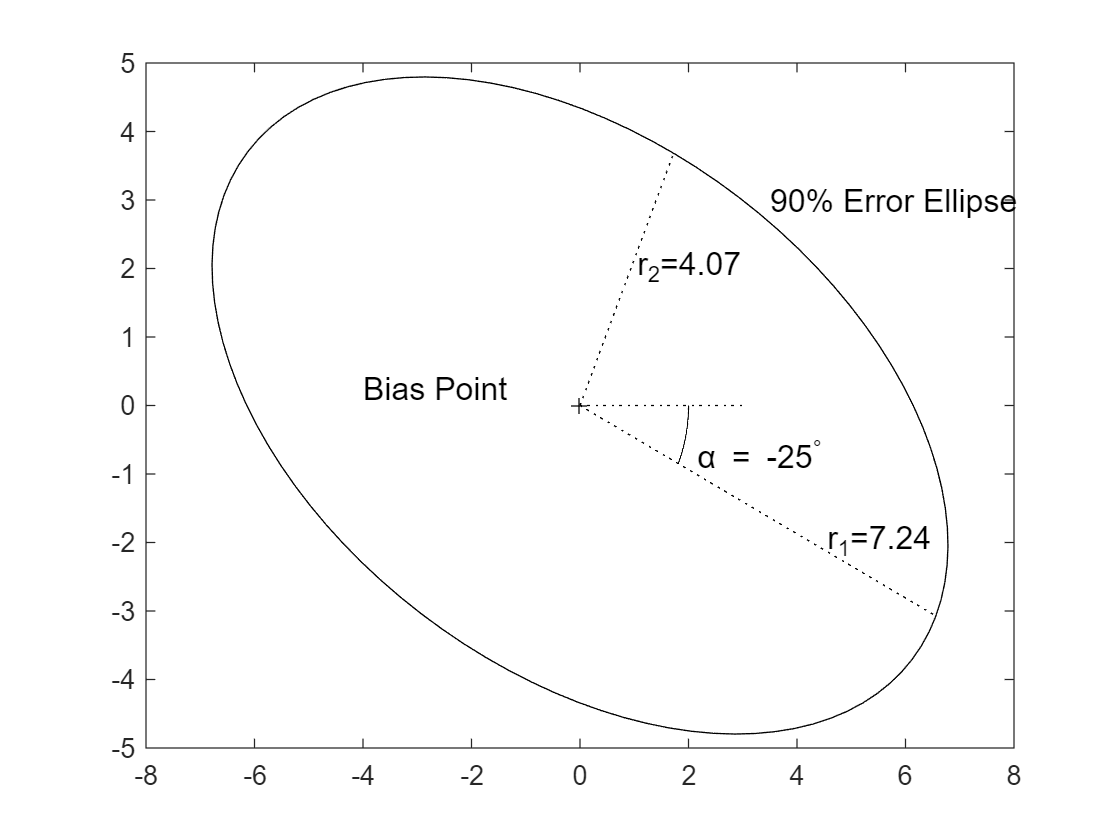

fig=figure;
plot(0,0,'k+','DisplayName','Bias Point');hold on;
text(-4,.25,'Bias Point','FontSize',12);
text(3.5,3,'90% Error Ellipse','FontSize',12);
plot(x,y,'k-','DisplayName','Error Ellipse');

% Draw the semi-minor and semi-major axes
plot([0 a*cos(alpha+pi)],[0 a*sin(alpha+pi)],'k:');
plot([0 -b*sin(alpha+pi)],[0 b*cos(alpha+pi)],'k:');
text(4.5,-2,'r_1=7.24','FontSize',12);
text(1,2,'r_2=4.07','FontSize',12);

plot([0 3],[0,0],'k:');
plot(2*cosd(0:-.1:-25),2*sind(0:-.1:-25),'k-','LineWidth',.5)
text(2.1,-.75,'\alpha = -25^\circ','FontSize',12);